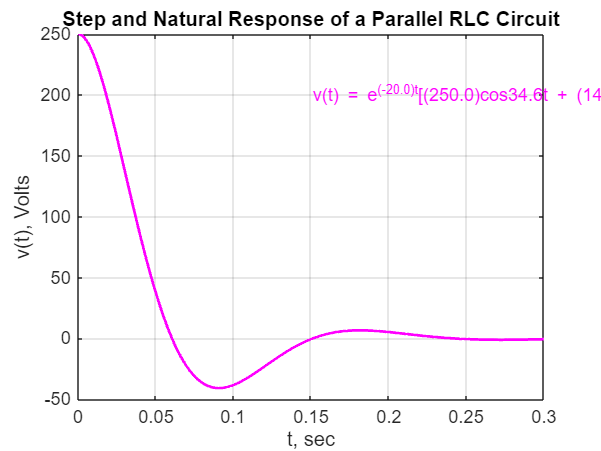

% Parameters of the circuit
R = 500; % Resistance in Ohms
L = 12.5; % Inductance in Henrys
C = 50e-6; % Capacitance in Farads
V0 = 250; % Initial voltage in Volts
I0 = 10; % Initial current in Amperes
Is = 4; % Source current in Amperes

% Calculate alpha and omega_0
alpha = 1 / (2 * R * C);
omega_0 = 1 / sqrt(L * C);

% Calculate damped frequency omega_d
omega_d = sqrt(omega_0^2 - alpha^2);

% Time vector for plotting
t = linspace(0, 0.3, 1000); % 0 to 0.3 seconds with 1000 points

% Coefficients A and B (from initial conditions)
A = V0;
% B = (I0 + (alpha * V0) + Is / C) / omega_d; % Corrected calculation of B
B = (I0 + (alpha * V0)) / omega_d;

% Voltage response v(t)
v_t = exp(-alpha * t) .* (A * cos(omega_d * t) + B * sin(omega_d * t));

% Plot the results
figure;
plot(t, v_t, 'm', 'LineWidth', 1.5);
grid on;
xlabel('t, sec');
ylabel('v(t), Volts');
title('Step and Natural Response of a Parallel RLC Circuit');
text(0.15, max(v_t) * 0.8, sprintf('v(t) = e^{(-%.1f)t}[(%.1f)cos%.1ft + (%.1f)sin%.1ft]', alpha, A, omega_d, B, omega_d), 'Color', 'magenta');


disp(sprintf('v(t) = e^{(-%.1f)t}[(%.1f)cos%.1ft + (%.1f)sin%.1ft]', alpha, A, omega_d, B, omega_d))

v(t) = e^{(-20.0)t}[(250.0)cos34.6t + (144.6)sin34.6t]
